H_image = rgb2gray(imread("C:\Users\pooja\Downloads\corner.jpg"));
corners1 = detectHarrisFeatures(H_image);
imshow(H_image); hold on;
plot(corners1);
corners1

corners1 =   1514×1 cornerPoints array with properties:

    Location: [1514×2 single]
      Metric: [1514×1 single]
       Count: 1514


[rows, columns, numberOfColorChannels] = size(H_image);
row1 = floor(rows - 30);
col1 = floor(columns - 35);
imshow(H_image)
% 5*5 pixels
subImage = imcrop(H_image, [col1, row1, 4, 4]);
subImage

subImage = 5×5 uint8 matrix
   141   142   143   143   143
   140   140   141   142   151
   140   140   141   141   159
   150   143   135   129   139
   154   149   144   140   143



corners2 = detectHarrisFeatures(subImage);
corners2

corners2 =   cornerPoints with properties:

    Location: [3.4329 2.0244]
      Metric: 4.5035e-08
       Count: 1


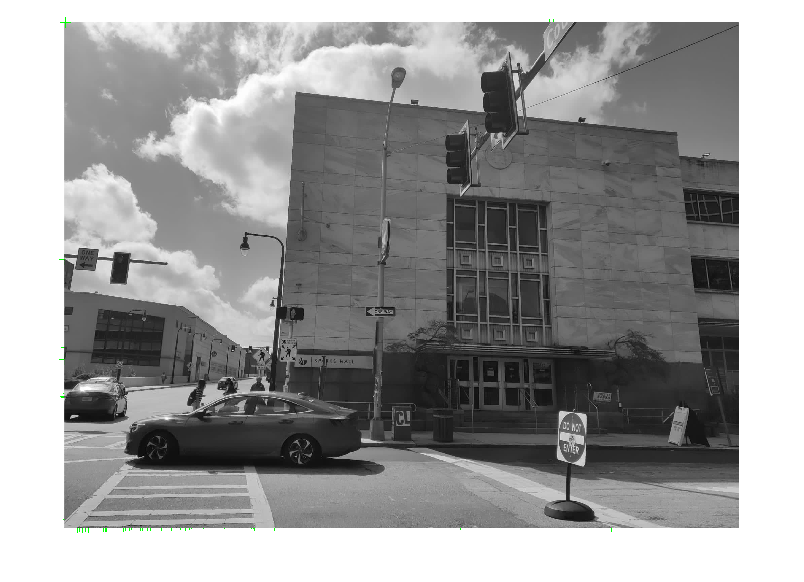

plot(corners2);